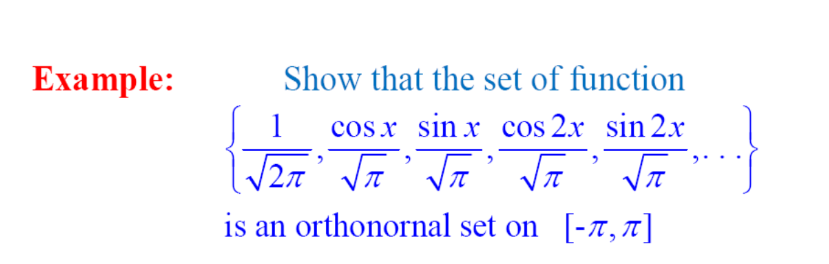

%check inner product
clear;
clc;
syms n x;
for n = 1 : 100
    m = randi(100);
    f = 1/sqrt(2*pi);
    f1 = cos(n*x)/sqrt(pi);
    f2 = sin(n*x)/sqrt(pi);
    f3 = cos(m*x)/sqrt(pi);
    f4 = sin(m*x)/sqrt(pi);
    eqn = int(f*f1,x,-pi,pi);
    eqn1 = int(f*f2,x,-pi,pi);
    eqn2 = int(f1*f3,x,-pi,pi);
    eqn3 = int(f2*f4,x,-pi,pi);
    eqn4 = int(f2*f3,x,-pi,pi);
    if n ~= m && eqn ==  0 && eqn1 == 0 && eqn2 ==0 && eqn3 == 0 && eqn4 == 0
        fprintf("set of function is an orthogonal set on [-pi,pi]")
        break
    else
           fprintf("set of function isn't an orthogonal set on [-pi,pi]")
    end
end    

set of function is an orthogonal set on [-pi,pi]